clc;
clear;
syms x f(x) u_e(x)

a=100

a = 100

c =0

c = 0


%f(x) = 4*x^2 - 2*x -4;
%exact_sol_f = -2*x^2+x;

f(x) = x^2

$$f(x) = x^{2}$$


% Solving Diffe equation

deqn = a*diff(u_e,x,2)+c*u_e == f;

Value1 = 0;
Value2 = 0;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
%ic2 = d_ue(1) == Value2;


ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;



% No of elements
e = 3;

% domain of X
x0 = 0;
xn = 1;
% Element length
h = (xn - x0) / e;

P=1   % P =7 is the Maximum this Code works

P = 1

ndofel=P+1;

pbar = max(2*P+ P - 2, P + P);

if mod(pbar, 2) == 1 % ODD
    n = (pbar + 1) / 2;
else % Even
    n = (pbar + 2) / 2;
end
n 

n = 2


[w,xi] = GaussQuadrature(n);

shapMatrix=zeros(n,ndofel);
dshapMatrix=zeros(n,ndofel);

for i = 1:n
    xi_loc = xi(i);
    [ndofel,shap,dshap] = SHAPE(P,xi_loc);

    for j =1:ndofel
        shapMatrix(i,j)=shap(j);
        dshapMatrix(i,j)=dshap(j);
    end

end
shapMatrix

shapMatrix =     0.2113    0.7887
    0.7887    0.2113


dshapMatrix

dshapMatrix =    -0.5000    0.5000
   -0.5000    0.5000



KNM_local=zeros(ndofel,ndofel);
CNM_local=zeros(ndofel,ndofel);

for i = 1:ndofel
    for j = 1:ndofel
        KNM_local(i, j)= 0;
        CNM_local(i, j)= 0;
        for k = 1:n
            KNM_local(i, j) = KNM_local(i, j)+ ((a * dshapMatrix(k,i) *dshapMatrix(k,j)*(2/h)*w(k)) - ( c * shapMatrix(k,i) *shapMatrix(k,j)*(h/2)*w(k)));
            CNM_local(i, j) = CNM_local(i, j)+ (-1 * shapMatrix(k,i) *shapMatrix(k,j)*(h/2)*w(k));
        end
    end
end
KNM_local

KNM_local =    300  -300
  -300   300


CNM_local

CNM_local =    -0.1111   -0.0556
   -0.0556   -0.1111



%generl formula for finding size of gloabl stiffness matrix-(S=OIF*e+1
S=P*e+1;
global_matrix_size = S; % each element has 2 nodal points
% Initialize global stiffness matrix


K_global = zeros(global_matrix_size);
C_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:ndofel-1:S-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + ndofel-1;
    K_global(start_index:end_index, start_index:end_index) = K_global(start_index:end_index, start_index:end_index) + KNM_local;
    C_global(start_index:end_index, start_index:end_index) = C_global(start_index:end_index, start_index:end_index) + CNM_local;
end

% Display global stiffness matrix
disp('Global Stiffness Matrix:')

Global Stiffness Matrix:


disp(K_global);

   300  -300     0     0
  -300   600  -300     0
     0  -300   600  -300
     0     0  -300   300



disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

   -0.1111   -0.0556         0         0
   -0.0556   -0.2222   -0.0556         0
         0   -0.0556   -0.2222   -0.0556
         0         0   -0.0556   -0.1111




X = (x0:h/P:xn)';

% Source vector Initialization 
f_x = zeros(S, 1);
% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:S
    f_x(i) = double(subs(f, x, X(i)));
end
%disp(f_x);

%K_global_inverse=InverseTDMA(K_global)

Fv = C_global*f_x

Fv =    -0.0062
   -0.0494
   -0.1605
   -0.1358



du_dx = Value2;

% Dirichlet Boundary Conditions

K_global_D_bc = K_global;
g_x_D_bc = sym(zeros(S, 1));
GNM_D_bc= a*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+Fv;

% Boundary Conditions1
u0 = Value1;
K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = Value2;
K_global_D_bc(end,:)= [zeros(1, S-1), 1];  %un=-1
RHS_D_bc(end) = un;  % RHS of equation

% for finding inverse I'm using My TDMA inverse function
K_global_D_bc_inverse=invLU(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc_inverse*RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point         u     
    ___________    ___________

            0                0
      0.33333      -0.00028807
      0.66667      -0.00041152
            1                0



disp("-------------------------------------------------------------")

-------------------------------------------------------------


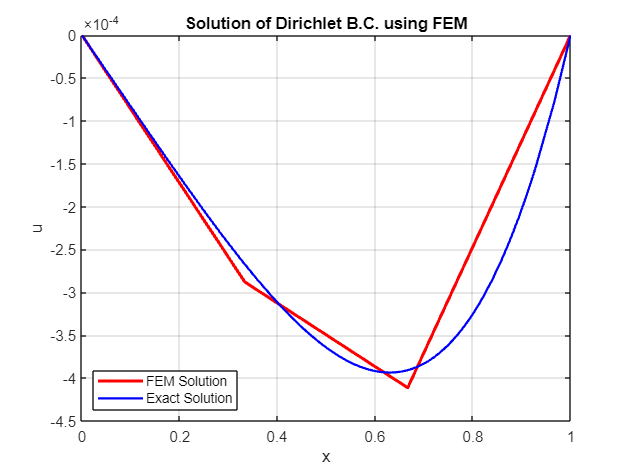

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [x0 xn], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;


du_dx = Value2; % at end point x = 1

% Neumann boundary Conditions
K_global_n_bc = K_global;
g_x_n_bc = sym(zeros(S, 1));
g_x_n_bc(end)=1;

GNM_n_bc= a*g_x_n_bc*du_dx;
RHS_n_bc = GNM_n_bc+Fv;

% Boundary Conditions1
u0 = Value1;
K_global_n_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_n_bc(1) = u0;  % RHS of equation


% for finding inverse I'm using My TDMA inverse function
K_global_n_bc_inverse=invLU(K_global_n_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_nodal = double(K_global_n_bc_inverse*RHS_n_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Neumann B.C. using FEM with Phantom Node is");

The Solution of Neumann B.C. using FEM with Phantom Node is


Table2 = table(X, u_nodal, 'VariableNames', {'Nodal point', 'u'});
disp(Table2);

    Nodal point        u     
    ___________    __________

            0               0
      0.33333      -0.0011523
      0.66667      -0.0021399
            1      -0.0025926



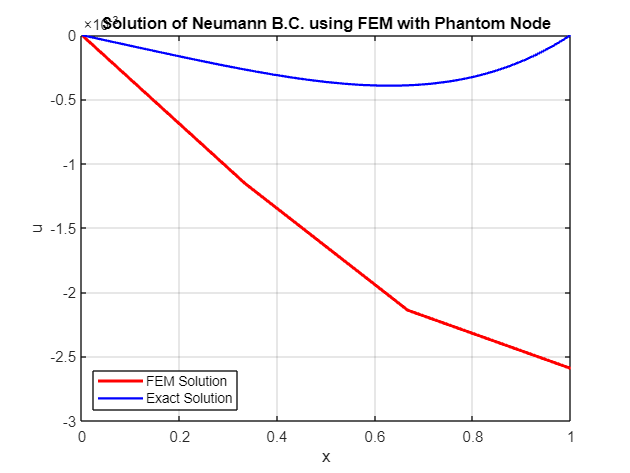


%Plot the FDM Solution and the actual solution
figure;
plot(X, u_nodal, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [x0 xn], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Neumann B.C. using FEM with Phantom Node");
legend('Location', 'southwest');
grid on;

function [w,xi] = GaussQuadrature(n)
w = zeros(n,1);
xi = zeros(n,1);
    if n==1
        w(1) = 2;
        xi(1) = 0;
    
    elseif n == 2
        w(1) = 1;
        w(2) = 1;
    
        xi(1) = sqrt(3)/3;
        xi(2) = -xi(1);
    elseif n == 3    
        w(1) = 5/9;
        w(2) = 5/9;
        w(3) = 8/9;
    
        xi(1) = sqrt(15)/5;
        xi(2) = -xi(1);
        xi(3) = 0;
    elseif n == 4
        w(1) = 1/2 + (sqrt(30)/36);
        w(2) = 1/2 + (sqrt(30)/36);
        w(3) = 1/2 - (sqrt(30)/36);
        w(4) = 1/2 - (sqrt(30)/36);
    
        xi(1) = sqrt((15-(2*sqrt(30)))/35);
        xi(2) = -xi(1);
        xi(3) = (sqrt(((14*sqrt(30))/5)+21))/7;
        xi(4) = -xi(3);
    elseif n == 5    
        w(1) = 0.236926885056189;
        w(2) = 0.236926885056189;
        w(3) = 0.478628670499366;
        w(4) = 0.478628670499366;
        w(5) = 0.568888888888889;
     
        xi(1) = 0.906179845938664;
        xi(2) = -xi(1);
        xi(3) = 0.538469310105683;
        xi(4) = -xi(3);
        xi(5) = 0;
    elseif n == 6    
        w(1) = 0.171324492379170;
        w(2) = 0.171324492379170;
        w(3) = 0.360761573048139;
        w(4) = 0.360761573048139;
        w(5) = 0.467913934572691;
        w(6) = 0.467913934572691;
     
        xi(1) = 0.932469514203152;
        xi(2) = -xi(1);
        xi(3) = 0.661209386466265;
        xi(4) = -xi(3);
        xi(5) = 0.238619186083197;
        xi(6) = -xi(5);
    elseif n == 7    
        w(1) = 0.129484966168870;
        w(2) = 0.129484966168870;
        w(3) = 0.279705391489277;
        w(4) = 0.279705391489277;
        w(5) = 0.381830050505119;
        w(6) = 0.381830050505119;
        w(7) = 0.417959183673469;
     
        xi(1) = 0.949107912342759;
        xi(2) = -xi(1);
        xi(3) = 0.741531185599394;
        xi(4) = -xi(3);
        xi(5) = 0.405845151377397;
        xi(6) = -xi(5);
        xi(7) = 0;
    elseif n == 8    
        w(1) = 0.101228536290376;
        w(2) = 0.101228536290376;
        w(3) = 0.222381034453374;
        w(4) = 0.222381034453374;
        w(5) = 0.313706645877887;
        w(6) = 0.313706645877887;
        w(7) = 0.362683783378362;
        w(8) = 0.362683783378362;
       
        xi(1) = 0.960289856497536;
        xi(2) = -xi(1);
        xi(3) = 0.796666477413627;
        xi(4) = -xi(3);
        xi(5) = 0.525532409916329;
        xi(6) = -xi(5);
        xi(7) = 0.183434642495650;
        xi(8) = -xi(7);
    elseif n == 9    
        w(1) = 0.081274388361574;
        w(2) = 0.081274388361574;
        w(3) = 0.180648160694857;
        w(4) = 0.180648160694857;
        w(5) = 0.260610696402935;
        w(6) = 0.260610696402935;
        w(7) = 0.312347077040003;
        w(8) = 0.312347077040003;
        w(9) = 0.330239355001260;
       
        xi(1) = 0.968160239507626;
        xi(2) = -xi(1);
        xi(3) = 0.836031107326636;
        xi(4) = -xi(3);
        xi(5) = 0.613371432700590;
        xi(6) = -xi(5);
        xi(7) = 0.324253423403809;
        xi(8) = -xi(7);
        xi(9) = 0;
    elseif n == 10    
        w(1) = 0.066671344308688;
        w(2) = 0.066671344308688;
        w(3) = 0.149451349150581;
        w(4) = 0.149451349150581;
        w(5) = 0.219086362515982;
        w(6) = 0.219086362515982;
        w(7) = 0.269266719309996;
        w(8) = 0.269266719309996;
        w(9) = 0.295524224714753;
        w(10) = 0.295524224714753;
        
        xi(1) = 0.973906528517172;
        xi(2) = -xi(1);
        xi(3) = 0.865063366688985;
        xi(4) = -xi(3);
        xi(5) = 0.679409568299024;
        xi(6) = -xi(5);
        xi(7) = 0.433395394129247;
        xi(8) = -xi(7);
        xi(9) = 0.148874338981631;
        xi(10) = -xi(9);
    end
end

function [ndofel,shap,dshap] = SHAPE(P,xi_loc)
    syms xi;
   
    ndofel=P+1;  % no of points
    
    xi_string = sym('xi', [1 ndofel]);
    shap = sym(zeros(ndofel,1));
    
    % Generating Lagrange interpolating polynomial
    for j = 1:ndofel
        % Compute the product term for each j
        product_term = 1;
        for k = 1:ndofel
            if k ~= j
                product_term = product_term * (xi - xi_string(k)) / (xi_string(j) - xi_string(k));
            end
        end 
        shap(j)= product_term;
    end
    
    dshap = diff(shap,xi);

    x_Loc = zeros(1,ndofel);
    for i = 1:ndofel
        x_Loc(i) = -1 + (i-1)*(2/P);
    end
    
    shap = subs(shap,xi_string,x_Loc);
    dshap = subs(dshap,xi_string,x_Loc);

    % substuting xi value and Transforming from column vector to row vector

    shap = double(subs(shap,xi,xi_loc))';
    dshap = double(subs(dshap,xi,xi_loc))';

end

function [A_inverse] = invLU(A)
%CroutsLU
    [m, n] = size(A);
    if m ~= n
        error('Input matrix must be square');
    end
    
    U = eye(n);  % Initialize L as identity matrix
    L = zeros(n); % Initialize U as zero matrix
    L(:,1) = A(:,1);
    U(1,:) = A(1,:)/L(1,1);

    for i = 2:n

        % Computing elements of L
        for k = i:n
            L(k, i) = A(k, i) - L(k, 1:i-1) * U(1:i-1, i);
        end

        %  Computing elements of U
        for j = i+1:n
            U(i, j) = (A(i, j) - L(i, 1:i-1) * U(1:i-1, j))/L(i,i);
        end
    end

    [n, ~] = size(L);
    % Identity matrix for b
    b = eye(n);
    
    x = zeros(n, n);
    
    % Solve Ly = b and then Ux = y for each column of b
    for col = 1:n
        y = zeros(n, 1);
    
        % Solve Ly = b (forward substitution)
        y(1) = b(1, col) / L(1, 1);
        for i = 2:n
            sum = b(i, col);
            for j = 1:i-1
                sum = sum - L(i, j) * y(j);
            end
            y(i) = sum / L(i, i);
        end
    
        % Solve Ux = y (backward substitution)
        x(n, col) = y(n);
        for i = n-1:-1:1
            sum = y(i);
            for j = i+1:n
                sum = sum - U(i, j) * x(j, col);
            end
            x(i, col) = sum / U(i, i);
        end
    end
    % Now,in  this x matrix contains the columns of the inverse of A
    A_inverse = x;
end

